Sprawozdanie nr 4

Data zajęć: 26.10.2023

Data wykonania sprawozdania: 08.11.2023

Temat: Analiza harmoniczna sygnałów

Istnieją dwa rodzaje sygnałów, ciągłe i dyskretne. Jednak w prawdziwym życiu zapisanie sygnału ciągłego do komputera jest związane z pewną specyfiką zapisu. Najczęściej korzysta się przetworników analogowo cyfrowych zamieniając sygnał w ciąg liczb które mają określoną reprezentację w systemie dwójkowym. . Prawidłowa zamiana sygnału ciągłego na cyfrowy oraz interpretacja wyników tej konwersji wymaga znajomości parametrów wejściowego sygnaśu ciągłego oraz takiego jego ukształtowania aby uzyskany sygnał cyfrowy możliwe jednoznacznie odwzorowywał właściwości sygnału ciągłego

Narzędziem pozwalającym na badanie sygnałów jest rozwijanie sygnału w szereg Fouriera. Pozwala to na modelowaniie procesu konwersji sygnału analogowego na cyfowy. 

Aby funkcja była rozwijalna w szereg Fouriera musi spełniać warunki Dirichleta, czyli:

- Funkcja jest bewzględnie całkowalna w całości jednego okresu.

- Funkcja posiada skończoną ilość ekstremów w każdym okresie.

- Funkcja posiada skończoną ilość punktów nieciągłości

Jeżeli te warunki są spełnione to sygnał można jednoznacznie opisać za pomocą zespolnego szregu Fouriera.Rozwinięcie sygnału w szereg Fouriera i transformacja odwrotna opisana może być za pomocą jednej z trzech postaci: wykładniczej, fazowej  i trygonometrycznej.

Właśności szeregów Fouriera:

Liniowość:

Liniowa kombinacja sygnałów jest równoznaczna z liniową kombinacją szeregów Fouriera tych sygnałów.

Af(t) +Bg(t) = AF+BG

f(t),g(t) to sygnały

F,G to szeregi Fouriera tych sygnałów, a A i B to stałe

Przesunięcie w czasie:

Przesunięcie sygnału jest równoznaczne z przemnożeniem szeregu Fouriera przez e^{−jnω0t1}.

Twierdzenie Parsevala:

Całka z kwadratu sygnału jest równa szeregowi Fouriera do kwadratu, inaczej energia sygnału ciągłego równa jest energii szeregu Fouriera wyznaczonej na jego podstawie.

Zadanie 1

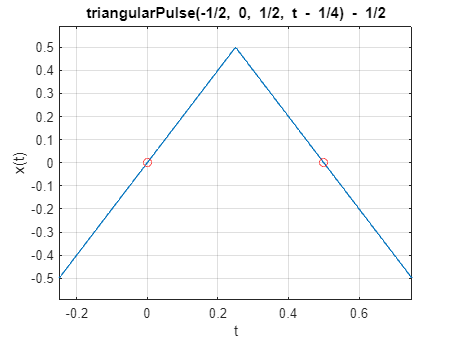


clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice calkowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
figure;

ezplot(x,BND); 
grid on; 
ylabel('x(t)');
hold on
plot([0,0.5],0,'ro')

Kod ćwiczenia tworzy sygnał trójkątny, ćwiczenie polega na zaznaczaniu miejsc zerowych funkcji która opisuje ten sygnał.

Zadnie 2

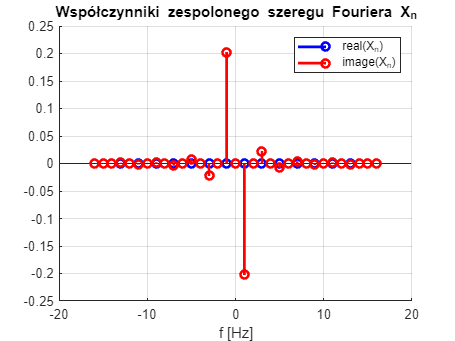

NT = 16;
X=[];
ind = -NT : NT;
for n = ind
Xn = (1/T0)*int(x*exp(-i*w0*n*t),t,BND);
X(n + NT + 1) = Xn;
end
figure; hold on;
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')

Kod ćwiczenia wyznacza współczyniki dla zespolonego szeregu  Fouriera i tworzy wykres na ich podstawie. Zadnaie polega tylko na zmianie ilości wyznaczanych funkcji bazowych

Zadanie 3

NT = 15;
An = zeros(1, 2 * NT + 1); % wektor do przechowywania współczynników wartości reczywistych
Bn = zeros(1, 2 * NT + 1); % wektor do przechowywania współczynników wartości urojonych

ind = -NT : NT;
offset= NT+1

offset = 16

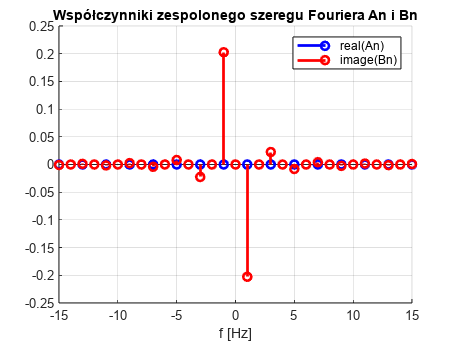

for i = ind
An(i+offset)=(1/T0)*int(x*cos(-w0*i*t),t,BND);
Bn(i+offset)=(1/T0)*int(x*sin(-w0*i*t),t,BND);
end
An;
Bn;

figure
hold on
stem(ind*f0,An,'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,Bn,'r','LineWidth',2);
grid on
legend('real(An)', 'image(Bn)', 'Location', 'NorthEast');
title('Współczynniki zespolonego szeregu Fouriera An i Bn')

Zadanie polega na odwzorwaniu kodu z Zadnia 2, tylko współczynniki szeregu Fouriera trzeba wyznaczyć dla postaci trygonometrycznej.Końcowa wersja kodu jest bardzo podobna, najwiekszą różnicą jest przechowywanie danych w dwóch wektorach zamiast jednego, znacznie różni się też wzór za pomocą którego wyznacza się współczynniki.

Zadanie 4

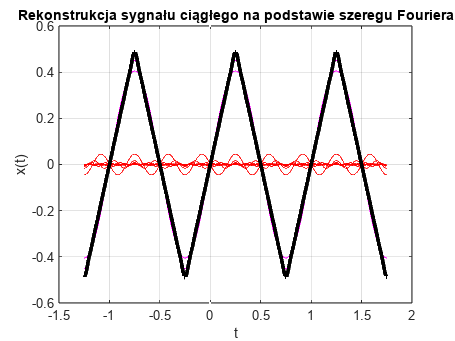

a=An;
b=Bn;
step = (BND(2) - BND(1))/1000;
tt = [BND(1)-0.5*T0: step: BND(2)+1.5*T0];
xx = zeros(1,length(tt));
xx = xx + a(offset); 
figure
plot(tt-0.5,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)');
pause(0.5)

for n = 1 :NT
    xx_n = 2*(a(n+offset)*cos(w0*n*tt) + b(n+offset)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt-0.5,xx_n,'r'); plot(tt-0.5,xx,'m');
    title(sprintf('n = %d',n+1)); pause(0.5)
end

plot(tt-0.5,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu Fouriera')

W kodzie zadanie zawarty jest szkielet rekonstrukcji sygnału, aby sygnał został poprawnie odwzorowany należy przypisać wektory ze współczynnikami z Zadania 3 tak by pasowały do szkieletu. Zmienić wartości tt tak by wyświetlały odpowiedni przedział i były przesunięte odpowiednio w fazie.

Wnioski:

- Szereg Fouriera pomaga w reprezentacji sygnału w komputerze. 

- Matlab jest oprogramowaniem, które bardzo dobrze nadaje się do operowania na sygnałach i korzystania z szeregów Fouriera

- Reprezentacja szeregu Fouriera jest możliwe na kilka sposobów i wyznaczanie wspólczynników szeregu w matlabie jest nieznacznie różne dla każdego sposobu.

- W matlabie można też dokonać rekonstrukcji sygnał, ale trzeba mieć pozostałe dane na temat oryginalengo syngału (same współczynniki szeregu fouriera nie wystarczą by idealnie odwzorować sygnał)